## Final Exam Review

## Exam 1

Question 1 is a problem review the initial and final value theorems:

- Initial Value Theorem: f (0+ ) = lim+ f (t) = as s -> infinity lim sF (s)

- Final Value Theorem: f (∞) = lim f (t) = lim sF (s) (s approaches 0)

clear;
syms s
Gs = (-2*(s+7)) / (s^2 -2*s+10)

$$Gs = -\frac{2\,s+14}{s^{2}-2\,s+10}$$

limGs = s*Gs

$$limGs = -\frac{s\,\left(2\,s+14\right)}{s^{2}-2\,s+10}$$

roots([1,-2,10])

ans =    1.0000 + 3.0000i
   1.0000 - 3.0000i


Question 2 is about Determining step response type:

- Overdamped ($$\zeta$$>1)

- Underdamped ($$\zeta$$<1)

- Critcally Damped ($$\zeta$$=1)

- Undamped ($$\zeta$$=0)

clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = 10*(s+3)/(s^2+30*s+200)


Gs =
 
     10 s + 30
  ----------------
  s^2 + 30 s + 200
 
Continuous-time transfer function.
Model Properties


secondOrderFromTF(Gs) %overdamped

poles =    -20
   -10


OS = -1.0000e+02 - 6.7380e-13i

Tp = 0.0000 - 0.6283i

Ts = 0.2667

Tr = 0.2640

ans = struct with fields:
      wn: 14.1421
    zeta: 1.0607



clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = (s+2)/(s^2+20*s+100)


Gs =
 
       s + 2
  ----------------
  s^2 + 20 s + 100
 
Continuous-time transfer function.
Model Properties


secondOrderFromTF(Gs) %crit damped

poles =    -10
   -10


OS = 0

Tp = Inf

Ts = 0.4000

Tr = 0.3382

ans = struct with fields:
      wn: 10
    zeta: 1



clear

s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = 17/(s^2+4*s+13)


Gs =
 
        17
  --------------
  s^2 + 4 s + 13
 
Continuous-time transfer function.
Model Properties


secondOrderFromTF(Gs) %underdamped

poles =   -2.0000 + 3.0000i
  -2.0000 - 3.0000i


OS = 12.3145

Tp = 1.0472

Ts = 2

Tr = 0.4849

ans = struct with fields:
      wn: 3.6056
    zeta: 0.5547



clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = (s+5)/(s^2+16)


Gs =
 
   s + 5
  --------
  s^2 + 16
 
Continuous-time transfer function.
Model Properties


secondOrderFromTF(Gs) %undamped

poles =    0.0000 + 4.0000i
   0.0000 - 4.0000i


OS = 100

Tp = 0.7854

Ts = Inf

Tr = 0.2500

ans = struct with fields:
      wn: 4
    zeta: 0


Question 2b is about step response parameters.

- These are found in the function used above

Question 3 - use laplace methods to solve for the complete solution for the following differential equation:


$$\[
\mathcal{L}\{x(t)\} = X(s)
\]

\[
\mathcal{L}\{\dot{x}(t)\} = sX(s) - x(0)
\]

\[
\mathcal{L}\{\ddot{x}(t)\} = s^2X(s) - s x(0) - \dot{x}(0)
\]

\[
\mathcal{L}\{t\} = \frac{1}{s^2}
\]
$$


clear;
syms s
Xs1 = (s^3-2*s^2+1)/(s^2*(s^2+1));
Xs = simplify(Xs1)

$$Xs = \frac{s^{3}-2\,s^{2}+1}{s^{2}\,\left(s^{2}+1\right)}$$


xt = ilaplace(Xs)

$$xt = t+\cos\left(t\right)-3\,\sin\left(t\right)$$

Question 4 - Initial Conditions of a circuit

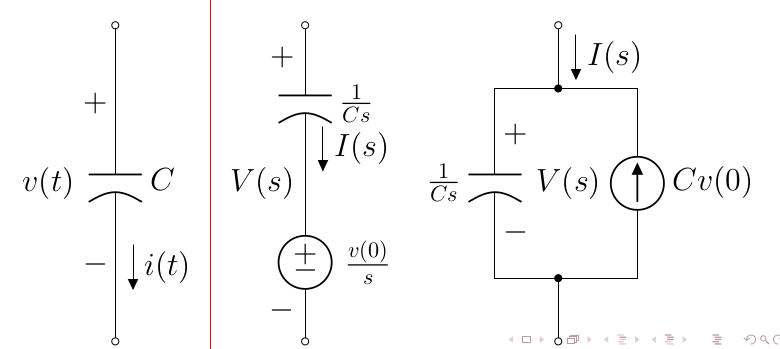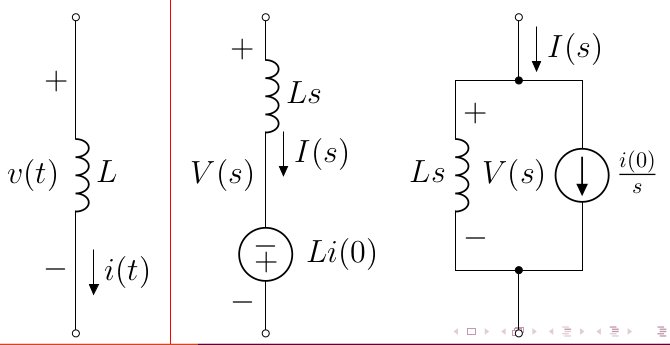

clear;
syms i1 i2 s

% Parameters
L = 0.8;         % H
C = 5e-6;        % F
R = 250;         % Ohms

% Initial conditions
iL0 = 9/250;     % Initial current through inductor
vC0 = 9;         % Initial voltage across capacitor

% Laplace impedances
ZL = L*s;
ZC = 1/(C*s);

% Voltage sources from initial conditions
VL0 = L*iL0;     % Initial inductor voltage source
IC0 = C*vC0;     % Initial capacitor current source (not directly used here)

% Modified KVL equations using superposition of impedance and initial sources
eqn1 = i1*ZL - VL0 + (i1 - i2)*ZC + vC0/s == 0;
eqn2 = i2*R + (i2 - i1)*ZC - vC0/s == 0;

[i1soln, i2soln] = solve(eqn1, eqn2, [i1, i2]);
i1simp = vpa(ilaplace(i1soln),6)

$$i1simp = 0.036\,{\mathrm{e}}^{-400.0\,t}\,\left(\cos\left(300.0\,t\right)+0.291667\,\sin\left(300.0\,t\right)\right)$$

i2simp = vpa(ilaplace(i2soln),6)

$$i2simp = 0.036\,{\mathrm{e}}^{-400.0\,t}\,\left(\cos\left(300.0\,t\right)+1.33333\,\sin\left(300.0\,t\right)\right)$$

Vct = vpa(i2simp * 250,6)

$$Vct = 9.0\,{\mathrm{e}}^{-400.0\,t}\,\left(\cos\left(300.0\,t\right)+1.33333\,\sin\left(300.0\,t\right)\right)$$

Question 4

Transfer function

clear;
syms Vo VA Vi s Z0 Z1
digits(6);
Z0subs = 500e3 + 1/(2e-6*s);
Z1subs = 200e3 + 1/(2e-6*s);
eqn = (-Vi)/Z0 + (-Vo) / Z1 ==0;
vout = solve(eqn,Vo) / Vi

$$vout = -\frac{Z_{1}}{Z_{0}}$$

Gs = subs(vout,{Z0,Z1},{Z0subs,Z1subs})

$$Gs = -\frac{\frac{2361183241434822606848}{4722366482869645\,s}+200000}{\frac{2361183241434822606848}{4722366482869645\,s}+500000}$$

Gs = simplify(vpa(Gs));
step = 1/s

$$step = \frac{1}{s}$$

Cs = Gs*step

$$Cs = -\frac{1.0\,\left(2.0\,s+5.0\right)}{s\,\left(5\,s+5.0\right)}$$

ct = ilaplace(Cs)

$$ct = 0.6\,{\mathrm{e}}^{-1.0\,t}-1.0$$